# 1. Diskretizacija funkcije

G_s = tf([0.1],[1,2,2,1])


G_s =
 
           0.1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


Ts = 0.1

Ts = 0.1000

H_z_tustin = c2d(G_s, Ts, 'tustin')


H_z_tustin =
 
  1.131e-05 z^3 + 3.393e-05 z^2 + 3.393e-05 z + 1.131e-05
  -------------------------------------------------------
              z^3 - 2.8 z^2 + 2.62 z - 0.8188
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


H_z_zoh = c2d(G_s, Ts, 'zoh')


H_z_zoh =
 
  1.585e-05 z^2 + 6.029e-05 z + 1.434e-05
  ---------------------------------------
      z^3 - 2.8 z^2 + 2.62 z - 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


## Odzivi sistemov na stopnico

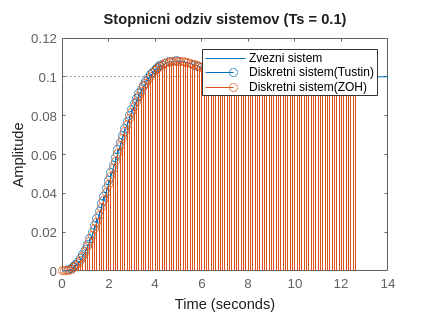

figure;
step(G_s);
hold on;
[y_d_tustin, t]=step(H_z_tustin);
stem(t, y_d_tustin);
hold on;
[y_d_zoh, t]=step(H_z_zoh);
stem(t, y_d_zoh);
title("Stopnicni odziv sistemov (Ts = 0.1)")
legend("Zvezni sistem", "Diskretni sistem(Tustin)", "Diskretni sistem(ZOH)")

## Odzivi sistemov na impulz

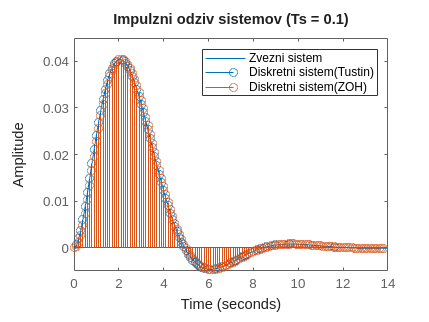

figure;
impulse(G_s);
hold on;
[y_d_tustin, t]=impulse(H_z_tustin);
stem(t, y_d_tustin);
hold on;
[y_d_zoh, t]=impulse(H_z_zoh);
stem(t, y_d_zoh);
title("Impulzni odziv sistemov (Ts = 0.1)")
legend("Zvezni sistem", "Diskretni sistem(Tustin)", "Diskretni sistem(ZOH)")

## Frekvencni odzivi sistemov

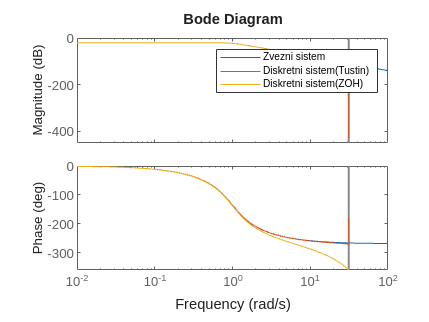

figure;
bode(G_s);
hold on;
bode(H_z_tustin);
hold on;
bode(H_z_zoh);
legend("Zvezni sistem", "Diskretni sistem(Tustin)", "Diskretni sistem(ZOH)")

## 2. Diskretizacija pri daljsem vzorcnem casu

G_s = tf([0.1],[1,2,2,1])


G_s =
 
           0.1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


Ts = 1

Ts = 1

H_z_tustin = c2d(G_s, Ts, 'tustin')


H_z_tustin =
 
  0.004762 z^3 + 0.01429 z^2 + 0.01429 z + 0.004762
  -------------------------------------------------
         z^3 - 1.19 z^2 + 0.7143 z - 0.1429
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


H_z_zoh = c2d(G_s, Ts, 'zoh')


H_z_zoh =
 
  0.009861 z^2 + 0.0233 z + 0.003628
  ----------------------------------
  z^3 - 1.154 z^2 + 0.657 z - 0.1353
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


## Odziv sistemov na stopnico

figure;
step(G_s);
hold on;
[y_d_tustin, t]=step(H_z_tustin);
stem(t, y_d_tustin);
hold on;
[y_d_zoh, t]=step(H_z_zoh);
stem(t, y_d_zoh);
title("Stopnicni odziv sistemov (Ts = 2)")
legend("Zvezni sistem", "Diskretni sistem(Tustin)", "Diskretni sistem(ZOH)")

## Odziv sistemov na impulz

figure;
impulse(G_s);
hold on;
[y_d_tustin, t]=impulse(H_z_tustin);
stem(t, y_d_tustin);
hold on;
[y_d_zoh, t]=impulse(H_z_zoh);
stem(t, y_d_zoh);
title("Impulzni odziv sistemov (Ts = 2)")
legend("Zvezni sistem", "Diskretni sistem(Tustin)", "Diskretni sistem(ZOH)")

## Frekvencni odzivi sistemov

figure;
bode(G_s);
hold on;
bode(H_z_tustin);
hold on;
bode(H_z_zoh);
legend("Zvezni sistem", "Diskretni sistem(Tustin)", "Diskretni sistem(ZOH)")
close all;

## 3. Simulacija diskretnega sistema

Ts = 0.1;
H_z_zoh = c2d(G_s, Ts, 'zoh');
[A,B,C,D] = ssdata(H_z_zoh)

A =     2.8002   -1.3099    0.8187
    2.0000         0         0
         0    0.5000         0


B =     0.0078
         0
         0


C =     0.0020    0.0039    0.0018


D = 0

H_z_zoh_ss = ss(A,B,C,D, Ts)


H_z_zoh_ss =
 
  A = 
           x1      x2      x3
   x1     2.8   -1.31  0.8187
   x2       2       0       0
   x3       0     0.5       0
 
  B = 
             u1
   x1  0.007812
   x2         0
   x3         0
 
  C = 
             x1        x2        x3
   y1  0.002029  0.003859  0.001836
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


[y_d_zoh_ss, t] = step(H_z_zoh_ss);
figure;
ks = 1:1:length(t)

ks =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


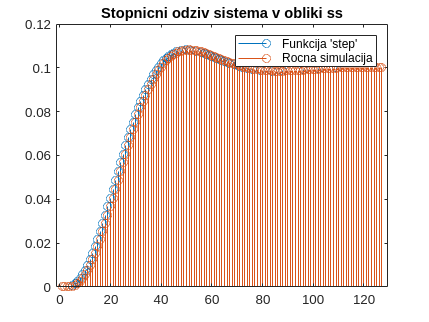

stem(ks, y_d_zoh_ss);
hold on;

u_k = ones(length(t));
x_k = zeros(size(A,1),length(t));
y_k = zeros(1,length(t));
u_k(1) = 0;
for i=1:length(t)
    x_k(:,i+1) = A*x_k(:,i)+B*u_k(i);
    y_k(:,i) = C*x_k(:,i)+D*u_k(i);
end

stem(ks, y_k);

legend("Funkcija 'step'", "Rocna simulacija")
title("Stopnicni odziv sistema v obliki ss")

## 4. Simulacija diskretnega P regulatorja

Ts = 0.1;
H_z_zoh = c2d(G_s, Ts, 'zoh');
ks = 1:1:128

ks =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



w_k = ones(1,length(ks));
x_k = zeros(1,length(ks));
y_k = zeros(1,length(ks));
e_k = zeros(1,length(ks));
u_k(1) = 0;
K = 20

K = 20

for i=2:length(ks)
    e(i) = w_k(i)-y_k(i-1)
    u_k(i) = K*e(i)
    y_k(i) = H_z_zoh(u_k(i))
end

e =      0     1


u_k =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    20     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

Error using  ()  (line 150)
Subscript no. 2 is out of range.


stem(ks, y_k);

legend("Funkcija 'step'", "Rocna simulacija")
title("Stopnicni odziv sistema v obliki ss")